 
clear 
% addpath(genpath('Functions'));
% addpath(genpath('Data'));
AircraftData_Ex;
fieldCodes=string(fieldnames(Aircrafts));


aircraftname=fieldCodes(3);
Aircraft=Aircrafts.(aircraftname);
    passengers=Aircraft.Pax;
    bags=Aircraft.Bags;
    cargo=Aircraft.Cargo;
    maxPyld = Aircraft.MaxPyld;
    range = Aircraft.Range;
    cruiseMach=Aircraft.CruiseMach;
    engines=Aircraft.Engines;
    paxWeight=Aircraft.PaxWeight;
    bagWeight=Aircraft.BagWeight;
    AR=Aircraft.AR;
    effic=Aircraft.e;
    CD0 = Aircraft.CD0;
    c_TO = Aircraft.c_TO;
    c_cruise = Aircraft.c_cruise;
    c_climb = Aircraft.c_climb;
    c_approach=Aircraft.c_approach;
    CL_TO = Aircraft.CL_TO;
    CL_ld = Aircraft.CL_Ld;
    gnrdRllFrac = Aircraft.groundRollFraciton;
    oeiPen = Aircraft.OEIPenalty;
    clmbDescCred = Aircraft.ClimbDescentCredit;
    we_A = Aircraft.We_A;
    We_Exp = Aircraft.We_exp;
    cruiseAlt = Aircraft.CruiseAlt;
    resRat = Aircraft.reserveRatio;


 
% if aircraftname ~= "Other"
%     AircraftData
% else
    %AircraftDataEntry
%
    Aircraft.Pax = 200;
    Aircraft.Bags = 200;
    Aircraft.Cargo = 0;
    Aircraft.MaxPyld = 35000;
    Aircraft.Range = 4500;
    Aircraft.CruiseMach = 0.84;
    Aircraft.Engines = 2;
    Aircraft.PaxWeight = 100;
    Aircraft.BagWeight = 0 ;
    Aircraft.AR = 10.2;
    Aircraft.e = 0.825;
    Aircraft.CD0 = 0.017;
    Aircraft.c_TO = 0.3;
    Aircraft.c_cruise = 0.515;
    Aircraft.c_climb = 0.515;
    Aircraft.c_approach = 0.515;
    Aircraft.CL_TO = 1.8  ;
    Aircraft.CL_Ld = 2.2;
    Aircraft.groundRollFraciton = 0.6;
    Aircraft.OEIPenalty = 0.5;
    Aircraft.ClimbDescentCredit = 200; %200 nautical miles
    Aircraft.We_A = 0.97;
    Aircraft.We_exp = -0.06;
    Aircraft.CruiseAlt = 36000;
    Aircraft.reserveRatio = 1.05;
%end
datatable = struct2table(Aircraft);
disp(strcat("Aircraft Name: ",aircraftname)), disp(datatable);

Aircraft Name: C
    Pax    Bags    Cargo    MaxPyld    Range    CruiseMach    Engines    PaxWeight    BagWeight     AR       e       CD0     c_TO    c_cruise    c_climb    c_approach    CL_TO    CL_Ld    groundRollFraciton    OEIPenalty    ClimbDescentCredit    We_A    We_exp    CruiseAlt    reserveRatio     TW     WS     Constraints
    ___    ____    _____    _______    _____    __________    _______

MissionSpec;
LoadMissionDefaults;

 
[MissionTable,Aircraft] = mission(missionDef,Aircraft,MissionDefaults);
[MTOW,Aircraft]=MTOWSolver(MissionTable,Aircraft);
Aircraft.MTOW=MTOW;
Range = pyldRangeEstimator(Aircraft,MissionTable);
Aircraft.RangemaxPyld = Range;
FerryRange=pyldRangeEstimator(Aircraft, MissionTable,0);
Aircraft.FerryRange = FerryRange;
MissionTbl=table(MissionTable.WeightFractions(:,1), MissionTable.WeightFractions(:,2), ...
    MissionTable.WeightFractions(:,3), 'VariableNames', ["Segment Fraction", "Mission Fraction", "Segment Type"]);
WeightTbl =table([Aircraft.MTOW; Aircraft.EmptyWeight; Aircraft.DesignPayload; Aircraft.MaxPyld; Aircraft.DesignFuel],'RowNames',["Max Takeoff Weight", "Empty Weight", "Design Payload", "Maximum Payload", "Aircraft Design Fuel"],'VariableNames',"Weights (kg)");
disp(MissionTbl), disp(WeightTbl);

    Segment Fraction    Mission Fraction    Segment Type
    ________________    ________________    ____________

       {[0.9950]}          {[0.9950]}         {'WARM'}  
       {[0.9900]}          {[0.9850]}         {'TKOF'}  
       {[0.9800]}          {[0.9653]}         {'CLMB'}  
       {[0.7641]}          {[0.7376]}         {'CRUS'}  
       {[0.9950]}          {[0.7339]}         {'DSCT'}  
       {[0.9950]}          {[0.7303]}         {'LNDG'}  
       {[0.9870]}          {[0.7208]}         {'HOLD'}  
       {[0.9990]}          {[0.7201]}         {'TAXI'}  
       {[0.9900]}          {[0.7129]}         {'ALCL'}  
       {[0.9938]}          {[0.7084]}         {'ALCR'}  
       {[0.9950]}          {[0.7049]}         {'ALLD'}  
       {[0.9524]}          {[0.6713]}         {'RSRV'}  

                            Weights (kg)
                            ____

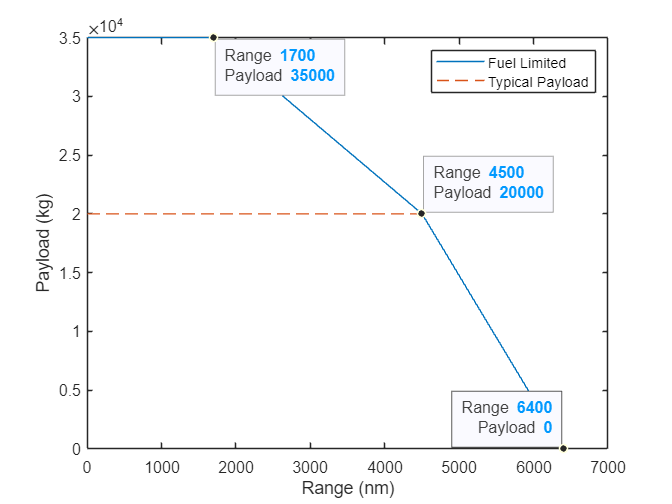

 
plot([0, Range, Aircraft.Range, FerryRange],[Aircraft.MaxPyld,Aircraft.MaxPyld,Aircraft.DesignPayload,0])
hold on
plot ([0, Range, Aircraft.Range],[Aircraft.DesignPayload,Aircraft.DesignPayload,Aircraft.DesignPayload],'--')
hold off
legend(["Fuel Limited", "Typical Payload"])

xlabel("Range (nm)")
ylabel("Payload (kg)")
ax = gca;
chart = ax.Children(1);
chart.DataTipTemplate.DataTipRows(1).Label="Range";
chart.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart,Aircraft.Range,Aircraft.DesignPayload);
chart2 =ax.Children(2);
chart2.DataTipTemplate.DataTipRows(1).Label="Range";
chart2.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart2,Aircraft.RangemaxPyld,Aircraft.MaxPyld);
ax2 = gca;
chart3 = ax2.Children(2);
datatip(chart3,Aircraft.FerryRange,0);

%
%
%

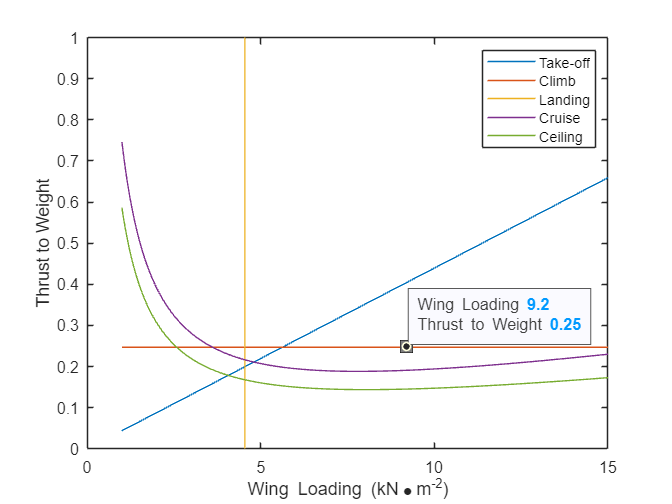

 
designPointX = 9.2;
designPointY= 0.25;
[Aircraft,Aircraft.Constraints] = ConstraintsAnalysis(Aircraft,Aircraft.Constraints,MissionTbl);
for ii = 1:length(Aircraft.Constraints)
    xdata(:,ii)=Aircraft.Constraints(ii).WS/1000;
    ydata(:,ii)=Aircraft.Constraints(ii).TW;
    legendData{ii}=Aircraft.Constraints(ii).Type;
end
Aircraft.WS=designPointX;
Aircraft.TW=designPointY;
WingLoading=Aircraft.WS;
ThrustoWeight = Aircraft.TW;
plot(xdata,ydata,designPointX,designPointY,'ks','MarkerSize',10,'MarkerFaceColor',[0.5,0.5,0.5])

%hold on
%plot(designPointX,designPointY,'x')
%hold off
xlabel("Wing Loading (kN\bulletm^{-2})");
ylabel("Thrust to Weight");
legend(legendData)

ax3 = gca;
chart4 = ax3.Children(1);
datatip(chart4,designPointX,designPointY);
chart4.DataTipTemplate.DataTipRows(1).Label="Wing Loading";
chart4.DataTipTemplate.DataTipRows(2).Label="Thrust to Weight";

Aircraft.WingArea = round((Aircraft.MTOW * 9.81)/(WingLoading*1000),2,"significant");
Aircraft.TotalThrust = round((Aircraft.MTOW * 9.81) * ThrustoWeight,3,"significant");
Aircraft.ThrustperEngine = round(Aircraft.TotalThrust/Aircraft.Engines,3,"significant");
AircraftTable = table([ThrustoWeight; WingLoading; Aircraft.WingArea; Aircraft.TotalThrust/1000; Aircraft.ThrustperEngine/1000], 'RowNames', ["Thrust to Weight", "Wing Loading (kN/m^2)", "Wing Area (m^2)", "Installed Thrust (kN)", "Engine Thrust (kN)"], 'VariableNames',["Values"]);
disp(AircraftTable)

                             Values
                             ______

    Thrust to Weight          0.25 
    Wing Loading (kN/m^2)      9.2 
    Wing Area (m^2)            120 
    Installed Thrust (kN)      270 
    Engine Thrust (kN)         135 

